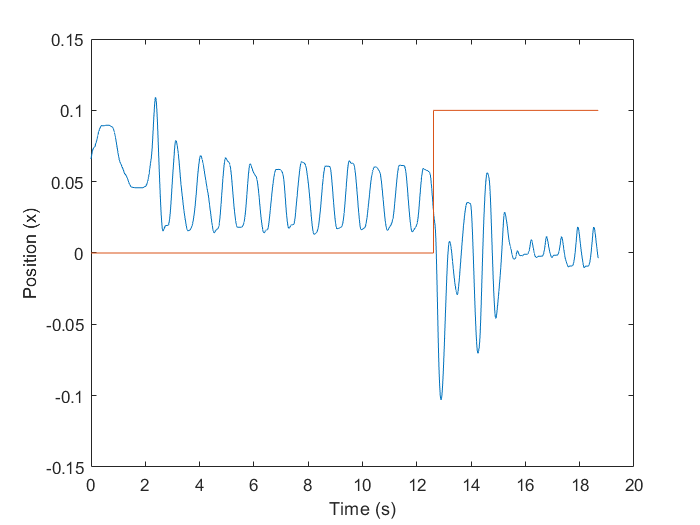

clear, clc;

load('trp46r4.mat');
data = trp46r4;

time_array = data.X.Data;
cart_position = data.Y(1).Data;
cart_position_gain = data.Y(2).Data;
cart_velocity = data.Y(3).Data; 
cart_velocity_gain = data.Y(4).Data;
tracking_gain = data.Y(5).Data; 
cart_position_command = data.Y(6).Data; 
pendulum_position_gain = data.Y(7).Data; 
pendulum_position = data.Y(8).Data;
pendulum_velocity = data.Y(9).Data;
pendulum_velocity_gain = data.Y(10).Data;
raw_motor_voltage = data.Y(11).Data; 

% Plot response
figure();
plot(time_array, cart_position)
hold on
plot(time_array, cart_position_command)
xlabel("Time (s)")
ylabel("Position (x)")

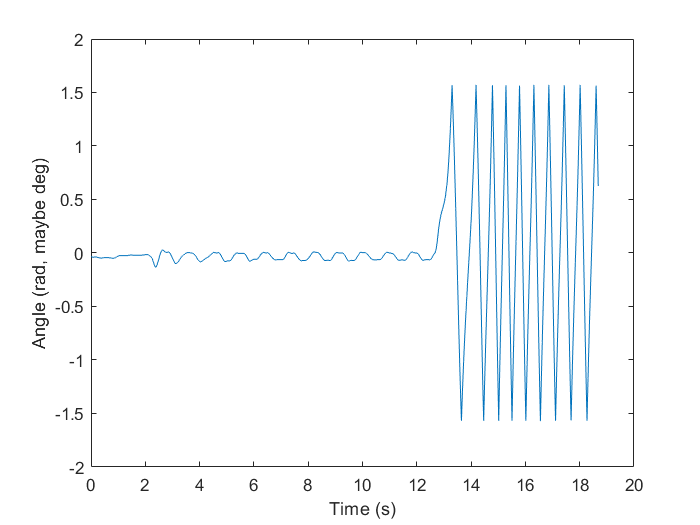

% legend("Cart position", "Input r")
 
% Plot theta, so we can check small angle approx
figure();
plot(time_array, pendulum_position)
xlabel("Time (s)")
ylabel("Angle (rad, maybe deg)")

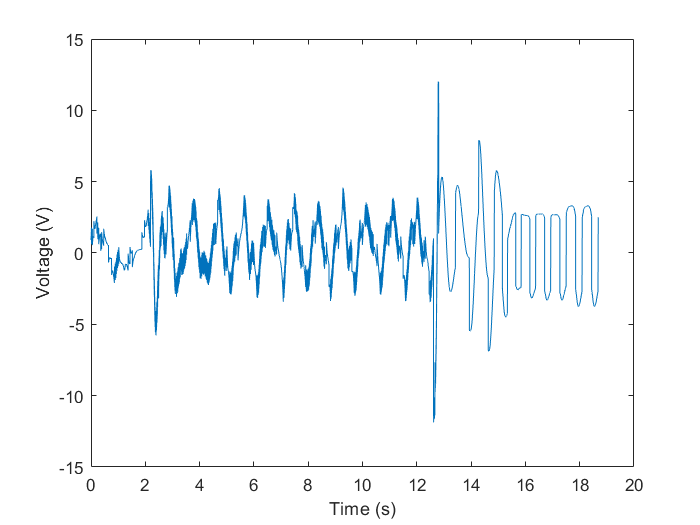


% Plot Voltage
figure();
plot(time_array, raw_motor_voltage)
xlabel("Time (s)")
ylabel("Voltage (V)")

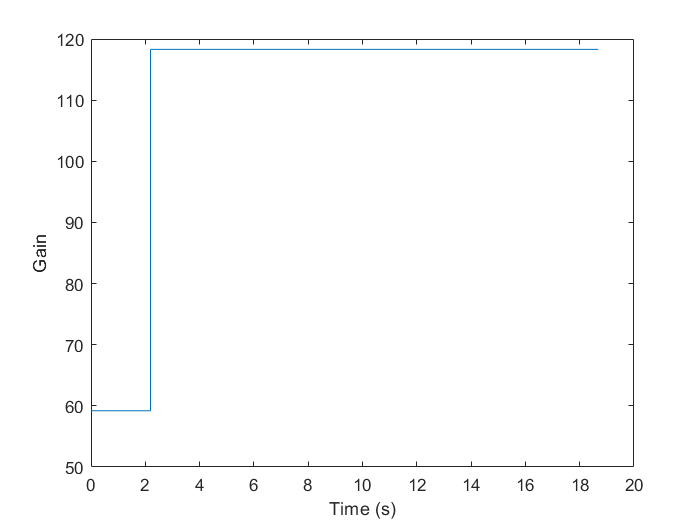


% Plot gains
figure();
plot(time_array, cart_position_gain)
xlabel("Time (s)")
ylabel("Gain")


% Print gains - mode takes the most common value
fprintf("Cart position gain: %d", mode(cart_position_gain));

Cart position gain: 1.183000e+02

fprintf("Pendulum position gain: %d", mode(pendulum_position_gain));

Pendulum position gain: 1.239000e+02

fprintf("Cart velocity gain: %d", mode(cart_velocity_gain));

Cart velocity gain: 5.120000e+01

fprintf("Pendulum velocity gain: %d", mode(pendulum_velocity_gain));

Pendulum velocity gain: 2.550000e+01